clear; clc;

%% === Auto setup project path ===
try
    if ~isempty(mfilename) && ~strcmp(mfilename,'LiveEditorEvaluationHelper')
        projectRoot = fileparts(mfilename('fullpath'));
    else
        projectRoot = fileparts(matlab.desktop.editor.getActiveFilename);
        if isempty(projectRoot), projectRoot = pwd; end
    end
catch
    projectRoot = pwd;
end
addpath(genpath(fullfile(projectRoot,'src')));
fprintf('[PATH] %s\n', fullfile(projectRoot,'src'));

[PATH] C:\Users\Fan Yi\AppData\Local\Temp\Editor_gtdic\src



% 统一输出目录
outDir = fullfile(projectRoot, 'results', 'ml');
if ~isfolder(outDir)
    mkdir(outDir);
end





%% Load feature data


load("results/ml/philharmonia_features.mat");

fprintf("Loaded %d samples, feature dim = %d\n", size(X,1), size(X,2));

Loaded 4169 samples, feature dim = 30


uniqueLabels = unique(Labels);
fprintf("Detected %d instruments:\n", numel(uniqueLabels));

Detected 7 instruments:


disp(uniqueLabels);

    "bassoon"
    "cello"
    "flute"
    "guitar"
    "oboe"
    "trombone"
    "tuba"



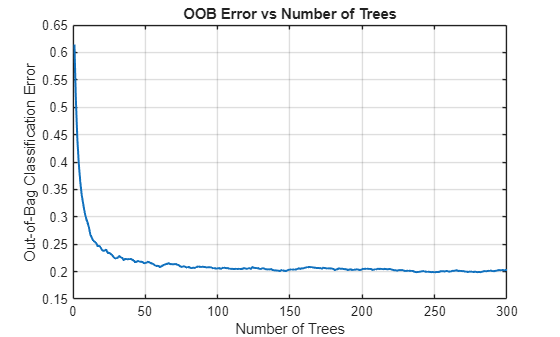

% ============ 1) 分层划分 + 标准化 ============
rng(42);                               % 固定随机种子，结果可复现
Y = categorical(Labels);               % 统一标签
cv = cvpartition(Y,'Holdout',0.2);     % 分层划分（每类都按比例进测试集）

Xtrain = X(training(cv),:);
Ytrain = Y(training(cv));
Xtest  = X(test(cv),:);
Ytest  = Y(test(cv));

mu = mean(Xtrain,1);
sigma = std(Xtrain,[],1);
Xtrain = (Xtrain - mu) ./ (sigma + 1e-6);
Xtest  = (Xtest  - mu) ./ (sigma + 1e-6);

% ============ 2) 随机森林（带 OOB 曲线） ============
MdlRF = TreeBagger(300, Xtrain, Ytrain, ...
    'Method','classification', ...
    'OOBPrediction','On', ...
    'OOBPredictorImportance','On', ...
    'MinLeafSize',5, ...
    'NumPredictorsToSample','all', ...
    'SampleWithReplacement','on');

figure; plot(oobError(MdlRF),'LineWidth',1.5); grid on;
xlabel('Number of Trees'); ylabel('Out-of-Bag Classification Error');
title('OOB Error vs Number of Trees');

exportgraphics(gcf, fullfile(outDir,'oob_error_rf.png'), 'Resolution',220);

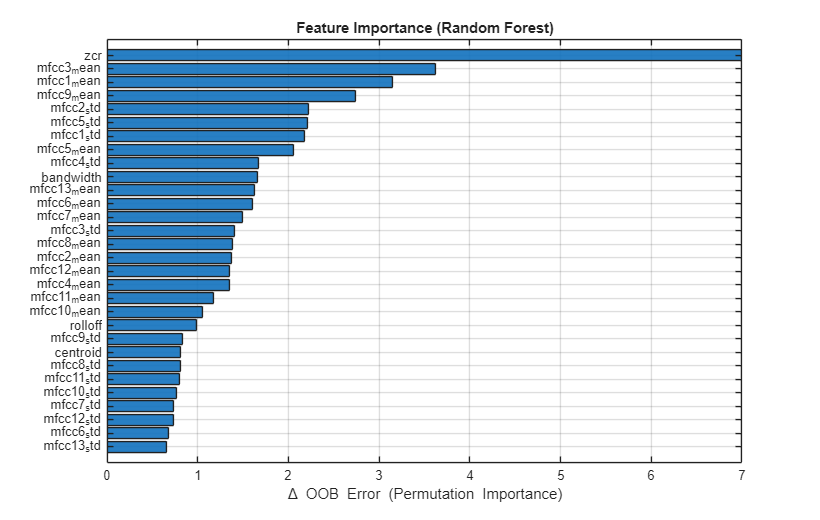




%% === Feature Importance (Random Forest) ===
% 要求 MdlRF 训练时开启了 'OOBPrediction','On' 和 'OOBPredictorImportance','On'
% 你前面已经这么设置了：TreeBagger(300, Xtrain, Ytrain, ... 'OOBPrediction','On', 'OOBPredictorImportance','On')

% 1) 拿重要性（如果属性不可用，退回到函数计算）
try
    imp = MdlRF.OOBPermutedPredictorDeltaError(:);
catch
    warning('Using oobPermutedPredictorImportance fallback.');
    imp = oobPermutedPredictorImportance(MdlRF);
    imp = imp(:);
end

% 2) 生成特征名（与你的 extract_features_local 一致）
%    次序： [centroid, bandwidth, rolloff, zcr, MFCC mean(1..N), MFCC std(1..N)]
p = numel(imp);
if exist('Xtrain','var')
    p = size(Xtrain,2);  % 以训练维度为准
end

if p < 4
    error('Feature dimension(%d) is smaller than 4; check your feature vector.', p);
end

remain = p - 4;
if mod(remain,2) ~= 0
    warning('Feature length(%d) not matching 4 + 2*N; naming MFCC generically.', p);
end
n_mfcc = max(1, floor(remain/2));

featNames = strings(1,p);
featNames(1:4) = ["centroid","bandwidth","rolloff","zcr"];
for k = 1:n_mfcc
    idx = 4 + k;
    featNames(idx) = "mfcc" + k + "_mean";
end
for k = 1:n_mfcc
    idx = 4 + n_mfcc + k;
    if idx <= p
        featNames(idx) = "mfcc" + k + "_std";
    end
end
% 兜底：若还有空名（极少数边界），补 generic 名称
emptyIdx = find(featNames=="");
for k = 1:numel(emptyIdx)
    featNames(emptyIdx(k)) = "feat_" + emptyIdx(k);
end

% 3) 排序并可视化（水平条形图，方便长标签）
[impSorted, idx] = sort(imp, 'descend');
figure('Name','Feature Importance (Random Forest)','Position',[100 100 820 520]);
barh(impSorted, 'FaceAlpha',0.9);
set(gca,'YDir','reverse','FontSize',10);
yticks(1:p);
yticklabels(featNames(idx));
xlabel('\Delta OOB Error (Permutation Importance)');
title('Feature Importance (Random Forest)');
grid on;


% 4) 打印 Top-K 特征（写报告直接用）
K = min(12, p);
T_top = table(featNames(idx(1:K)).', impSorted(1:K), ...
              'VariableNames',{'Feature','DeltaOOBError'});
disp('Top-K important features (Random Forest):');

Top-K important features (Random Forest):


disp(T_top);

       Feature       DeltaOOBError
    _____________    _____________

    "zcr"                6.999    
    "mfcc3_mean"        3.6219    
    "mfcc1_mean"        3.1518    
    "mfcc9_mean"        2.7359    
    "mfcc2_std"         2.2178    
    "mfcc5_std"         2.2147    
    "mfcc1_std"         2.1736    
    "mfcc5_mean"        2.0573    
    "mfcc4_std"         1.6688    
    "bandwidth"         1.6538    
    "mfcc13_mean"       1.6292    
    "mfcc6_mean"        1.6066    




% 5) 组别汇总（谱域基础特征 vs MFCC mean vs MFCC std）
grp_basic = ismember(featNames, ["centroid","bandwidth","rolloff","zcr"]);
grp_mean  = startsWith(featNames, "mfcc") & endsWith(featNames, "_mean");
grp_std   = startsWith(featNames, "mfcc") & endsWith(featNames, "_std");

sum_basic = sum(imp(grp_basic));
sum_mean  = sum(imp(grp_mean));
sum_std   = sum(imp(grp_std));

T_group = table( ["spectral_basic";"mfcc_mean";"mfcc_std"], ...
                 [sum_basic; sum_mean; sum_std], ...
                 'VariableNames',{'Group','TotalImportance'});
disp('Grouped importance summary:');

Grouped importance summary:


disp(T_group);

         Group          TotalImportance
    ________________    _______________

    "spectral_basic"        10.454     
    "mfcc_mean"             23.975     
    "mfcc_std"              15.691     



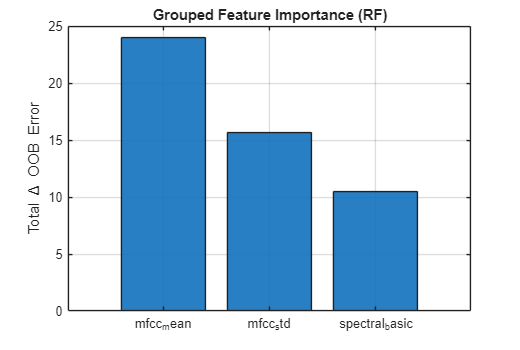


figure('Name','Grouped Importance','Position',[100 100 520 350]);
bar(categorical(T_group.Group), T_group.TotalImportance, 'FaceAlpha',0.9);
ylabel('Total \Delta OOB Error');
title('Grouped Feature Importance (RF)');
grid on;







% ============ 3) SVM（更稳默认：自动尺度 + 较强 Box） ============
tpl = templateSVM('KernelFunction','rbf','KernelScale','auto','BoxConstraint',8);
MdlSVM = fitcecoc(Xtrain, Ytrain, 'Coding','onevsone', 'Learners', tpl);

% ============ 3b) 再加两个基线模型 ============
MdlKNN = fitcknn(Xtrain, Ytrain, 'NumNeighbors', 5, 'Distance','cosine');     % kNN
MdlNB  = fitcnb( Xtrain, Ytrain, 'DistributionNames','kernel');               % 朴素贝叶斯


% ============ 4) 四模型统一对比，自动选最好 ============

% 统一类别顺序，避免预测类型不一致
ord = categories(Y);

% 用本地函数做安全预测（见文末 local_predict_cat）
predict_cat = @(mdl,X) local_predict_cat(mdl, X, ord);

% 逐个预测
Yhat_RF  = predict_cat(MdlRF,  Xtest);
Yhat_SVM = predict_cat(MdlSVM, Xtest);
Yhat_KNN = predict_cat(MdlKNN, Xtest);
Yhat_NB  = predict_cat(MdlNB,  Xtest);

% 计算准确率
acc_RF  = mean(Yhat_RF  == categorical(Ytest,ord));
acc_SVM = mean(Yhat_SVM == categorical(Ytest,ord));
acc_KNN = mean(Yhat_KNN == categorical(Ytest,ord));
acc_NB  = mean(Yhat_NB  == categorical(Ytest,ord));

fprintf('RF Acc  = %.2f%% | SVM Acc = %.2f%% | kNN Acc = %.2f%% | NB Acc = %.2f%%\n', ...
        acc_RF*100, acc_SVM*100, acc_KNN*100, acc_NB*100);

RF Acc  = 81.63% | SVM Acc = 87.88% | kNN Acc = 83.19% | NB Acc = 64.95%



% 组成一个列表，选最优
names = ["Random Forest","SVM (RBF)","kNN","Naive Bayes"];
accs  = [acc_RF, acc_SVM, acc_KNN, acc_NB];
yhats = {Yhat_RF,  Yhat_SVM, Yhat_KNN, Yhat_NB};
mdls  = {MdlRF,    MdlSVM,   MdlKNN,   MdlNB};

[bestAcc, idx] = max(accs);
bestName = names(idx);
Ypred    = yhats{idx};
Mdl      = mdls{idx};

fprintf('✅ Using model: %s | Test Acc = %.2f%%\n', bestName, bestAcc*100);

✅ Using model: SVM (RBF) | Test Acc = 87.88%







order = categories(Y);
% ===== 批量导出评估产物：混淆矩阵图、每类P/R/F1、汇总CSV =====
models   = {'RandomForest','SVM_RBF','kNN_5','NaiveBayes'};
predList = {Yhat_RF,       Yhat_SVM,  Yhat_KNN, Yhat_NB };

Summary = [];
for i = 1:numel(models)
    [acc_i, macroF1_i, C_i, T_i] = local_eval_metrics(Ytest, predList{i}, order);

    % 混淆矩阵图片（行归一化）
    f = figure('Name',['Confusion - ' models{i}],'Position',[100 100 780 540]);
    cm = confusionchart(categorical(Ytest,order), categorical(predList{i},order), ...
        'Normalization','row-normalized');
    cm.RowSummary='row-normalized'; cm.ColumnSummary='column-normalized';
    cm.Title = sprintf('Confusion Matrix (%s)', models{i});
    exportgraphics(f, fullfile(outDir, sprintf('confmat_%s.png', models{i})), 'Resolution',220);
    close(f);

    % 每类P/R/F1导出
    writetable(T_i, fullfile(outDir, sprintf('perclass_%s.csv', models{i})));

    Summary = [Summary; {models{i}, acc_i, macroF1_i}]; %#ok<AGROW>
end

Tsum = cell2table(Summary, 'VariableNames', {'Model','Accuracy','MacroF1'});
writetable(Tsum, fullfile(outDir,'model_eval_summary.csv'));
disp(Tsum);

         Model          Accuracy    MacroF1
    ________________    ________    _______

    {'RandomForest'}    0.81633     0.81701
    {'SVM_RBF'     }    0.87875     0.87049
    {'kNN_5'       }    0.83193     0.82044
    {'NaiveBayes'  }    0.64946     0.62716










% ============ 5) 更全面的评估：confusion + per-class F1 ============
order = categories(Y);    % 固定类别顺序，避免空类缺失
[C, order] = confusionmat(categorical(Ytest,order), categorical(Ypred,order));

prec = diag(C) ./ max(1, sum(C,1))';   % precision：按列
rec  = diag(C) ./ max(1, sum(C,2));    % recall：按行
f1   = 2*prec.*rec ./ max(1e-12,prec+rec);
macroF1 = mean(f1);

fprintf('Overall Accuracy: %.2f%% | Macro-F1: %.2f%%\n', ...
        mean(Ypred==Ytest)*100, macroF1*100);

Overall Accuracy: 87.88% | Macro-F1: 87.05%


disp(table(order,prec,rec,f1,'VariableNames',{'Class','Precision','Recall','F1'}));

     Class      Precision    Recall       F1   
    ________    _________    _______    _______

    bassoon      0.89744     0.79545    0.84337
    cello        0.86842       0.792    0.82845
    flute         0.8253     0.90728    0.86435
    guitar             1     0.77273    0.87179
    oboe             0.9     0.82759    0.86228
    trombone        0.85     0.92169    0.88439
    tuba         0.92929     0.94845    0.93878



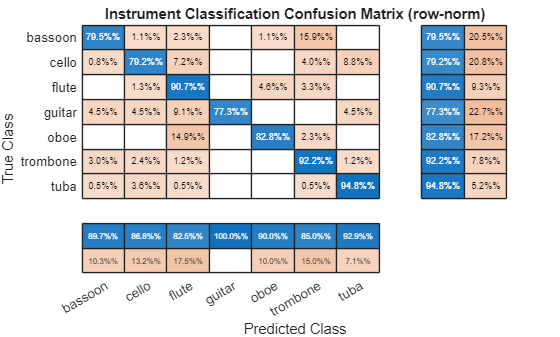


figure;
cm = confusionchart(categorical(Ytest,order), categorical(Ypred,order), ...
    'Normalization','row-normalized');
cm.CellLabelFormat = '%.1f%%';
cm.RowSummary = 'row-normalized';
cm.ColumnSummary = 'column-normalized';
cm.Title = "Instrument Classification Confusion Matrix (row-norm)";

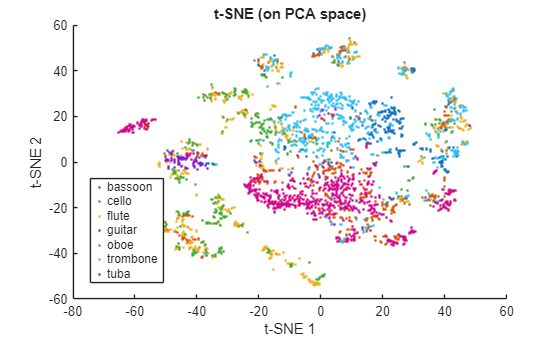


% ============ 6) t-SNE（先 PCA 再降维，更稳更快） ============
[coeff,score,~,~,expl] = pca(Xtrain);
k = find(cumsum(expl)>95,1);         % 保留 95% 方差
Z = tsne(score(:,1:k),'Perplexity',30,'Standardize',true);
figure; gscatter(Z(:,1),Z(:,2),Ytrain);
title('t-SNE (on PCA space)'); xlabel('t-SNE 1'); ylabel('t-SNE 2');


% ============ 7) 保存模型 ============
uniqueLabels = categories(Y);
bestModelName = char(bestName);
metrics = struct('RF',acc_RF,'SVM',acc_SVM,'kNN',acc_KNN,'NB',acc_NB, ...
                 'BestAcc',bestAcc,'BestName',bestModelName,'MacroF1',macroF1);
save(fullfile(outDir,"instrument_classifier.mat"), ...
     "Mdl","mu","sigma","uniqueLabels","bestModelName","metrics");
disp("Model saved -> " + fullfile(outDir,"instrument_classifier.mat"));

Model saved -> C:\Users\Fan Yi\AppData\Local\Temp\Editor_gtdic\results\ml\instrument_classifier.mat




function ycat = local_predict_cat(mdl, X, ord)
% 统一把不同模型的 predict 输出转成 categorical
    y = predict(mdl, X);
    ycat = local_toCat(y, ord);
end

function ycat = local_toCat(y, ord)
% 把 cell/char/string/categorical 统一为 categorical，且按指定顺序 ord
    if iscategorical(y)
        ycat = categorical(y, ord);
    elseif iscell(y)
        ycat = categorical(string(y), ord);
    elseif isstring(y)
        ycat = categorical(y, ord);
    elseif ischar(y)
        ycat = categorical(string(y), ord);
    else
        % 数值/逻辑等其它情况，兜底转字符串
        ycat = categorical(string(y), ord);
    end
end

function [acc, macroF1, C, tbl] = local_eval_metrics(Ytrue, Ypred, classes)
% 计算 Accuracy / Macro-F1 / 混淆矩阵 / 每类P/R/F1表
Ytrue = categorical(Ytrue, classes);
Ypred = categorical(Ypred, classes);
C = confusionmat(Ytrue, Ypred, 'Order', classes);

prec = diag(C) ./ max(1, sum(C,1))';   % 列
rec  = diag(C) ./ max(1, sum(C,2));    % 行
f1   = 2*prec.*rec ./ max(1e-12,prec+rec);

acc = mean(Ytrue == Ypred);
macroF1 = mean(f1);

tbl = table(classes, prec, rec, f1, ...
    'VariableNames',{'Class','Precision','Recall','F1'});
end

